# Slosh 2D - Tilt y

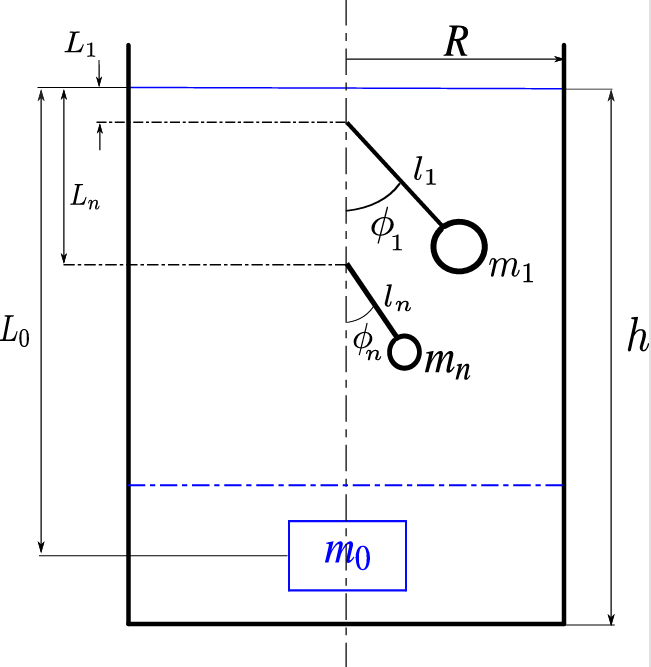

In this code the equation of motion for the pendulum angles representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent the 1D motion of the pivot, but it is the same for any point with a displacement along z of the cylinder axis.

clc 
clear all

syms theta(t) beta(t)
syms t 
syms h l m g b
syms x(t) y z(t) d dx dz

$\theta$ = rotation about Y describing the sloshing

$\beta$ = pitch rotation about the y axis of the container

l = length of pendulum

m = mass of pendulum

## Derivation of the pendulum coordinatesè-

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid mass in the world reference frame. 

% Second rotation about y
R_y_beta = [cos(beta),  0,  sin(beta);
              0,            1,            0;
             -sin(beta),  0,  cos(beta)];

R = R_y_beta

$$R(t) = \left(\begin{array}{ccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [x; y; z];

Define the transformation

T_wc = [R, p; 0 0 0 1];
T_wc = formula(T_wc);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_wc);

$$\left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & 0 & \sin\left(\beta \left(t\right)\right) & x\left(t\right)\\ 0 & 1 & 0 & y\\ -\sin\left(\beta \left(t\right)\right) & 0 & \cos\left(\beta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from inertial frame to pivot

% Second rotation about y
R_y_theta = [cos(theta),  0,  sin(theta);
              0,            1,            0;
             -sin(theta),  0,  cos(theta)];

R = R_y_theta

$$R(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (distance of center of rotation from the container base frame)

% p = [dx; 0; dz];
p = [0; 0; d];

Define the transformation

T_cp = [R, p; 0 0 0 1];
T_cp = formula(T_cp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to pivot:');

Homogeneous Transformation Matrix from world to pivot:


disp(T_cp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Homogeneous Transformation from pivot to mass

Define translation vector

p = [0; 0; -l];

Homogeneous transformation

T_pm = [eye(3), p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wc*T_cp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+d\,\sin\left(\beta \left(t\right)\right)-l\,\left(\cos\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

ym = T_wm(2,4)

$$ym = y$$

zm = T_wm(3,4)

$$zm = z\left(t\right)+l\,\left(\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)$$

Pendulum mass wrt pivot

Tr = T_cp*T_pm;
xr = Tr(1,4)

$$xr = -l\,\sin\left(\theta \left(t\right)\right)$$

yr = Tr(2,4)

$$yr = 0$$

zr = Tr(3,4) - d

$$zr = -l\,\cos\left(\theta \left(t\right)\right)$$

**If **$R_y(\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
-l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


**If **$R_y(-\theta)$**:**


$$p_m =$$

$$\left(\begin{array}{c}
l\,\sin \left(\theta \left(t\right)\right)\\
0\\
-l\;\cos \left(\theta \left(t\right)\right)
\end{array}\right)$$


## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

xr_dot = diff(xr, t);
yr_dot = diff(yr, t);
zr_dot = diff(zr, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = 0$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(l\,\left(\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

$$Tm = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(l\,\left(\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}$$

T = Tm;


$$T_m =\frac{m\,{{\left(-\frac{\partial }{\partial t}\mathrm{\ }\textrm{xt}\left(t\right)+\textrm{dy}\,\cos \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+\textrm{dx}\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)-l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }\textrm{zt}\left(t\right)+l\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)\right)}}^2 }{2}+\frac{m\,{{\left(\frac{\partial }{\partial t}\mathrm{\ }\textrm{yt}\left(t\right)+\textrm{dx}\,\cos \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)-\textrm{dy}\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)+l\,\cos \left(\gamma \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)+l\,\cos \left(\phi \left(t\right)\right)\,\cos \left(\theta \left(t\right)\right)\,\sin \left(\gamma \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\theta \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\gamma \left(t\right)-l\,\sin \left(\gamma \left(t\right)\right)\,\sin \left(\phi \left(t\right)\right)\,\sin \left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{\ }\phi \left(t\right)\right)}}^2 }{2}$$


### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)-l\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\right)$$


$$U=g\,m\,{\left(h+\textrm{zt}\left(t\right)-l\,\cos \left(\theta \left(t\right)\right)\right)}-M\,g\,{\left(\textrm{dz}-\textrm{zt}\left(t\right)\right)}$$


### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);

v2_theta = xr_dot^2 + yr_dot^2+ zr_dot^2

$$v2\_theta = l^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$


D_t = b/2 *(v2_theta);


% D = c/2 *(theta_dot^2);
D_dthetadot = diff(D_t, theta_dot)

$$D\_dthetadot(t) = \frac{b\,\left(2\,l^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+2\,l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}{2}$$

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)

$$L = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)-l\,\left(\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}+\frac{m\,{\left(l\,\left(\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)+\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{2}-g\,m\,\left(z\left(t\right)-l\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\right)$$


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)

$$L\_theta = d\,l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}-g\,l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)+l\,m\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}z\left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,m\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}z\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+d\,l\,m\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)$$

### Equation of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,l^{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)+g\,l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)-l\,m\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-d\,l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}-d\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,l^2\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)+g\,l\,m\,\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)-l\,m\,\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)-d\,l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2-d\,l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)




syms c_theta s_theta c_beta s_beta c_theta_beta s_theta_beta
syms theta_dot theta_ddot beta_dot beta_ddot x_ddot z_ddot 
eq_sub1 = subs(eqn_theta,[cos(theta(t)), sin(theta(t)), cos(beta(t)),sin(beta(t))],[c_theta s_theta c_beta s_beta]);
eq_sub2 = subs(eq_sub1, [diff(diff(theta(t),t),t),diff(diff(beta(t),t),t),diff(diff(x(t),t),t),diff(diff(z(t),t),t)],[theta_ddot,beta_ddot,x_ddot,z_ddot ]);
eq_sub3 = subs(eq_sub2, [diff(theta(t),t),diff(beta(t),t)],[theta_dot,beta_dot]);
eq_sub3 = simplify(eq_sub3);

% eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
eqn1 = isolate(eq_sub3 == 0, theta_ddot);
eqn1 = collect(eqn1, [x_ddot, z_ddot, g, beta_dot^2, beta_ddot, theta_dot]);

disp(eqn1);

$$\ddot{\theta }=\frac{\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\,\ddot{x}+\left(-\frac{\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\right)\,\ddot{z}+\left(-\frac{\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\right)\,g+\frac{d\,s_{\theta }}{l}\,{\dot{\beta }}^{2}+\left(-\frac{l^{2}\,m-c_{\theta }\,d\,l\,m}{l^{2}\,m}\right)\,\ddot{\beta }+\left(-\frac{b}{m}\right)\,\dot{\theta }$$

disp(latex(eqn1));

\ddot{\theta }=\frac{\cos\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\,\ddot{x}+\left(-\frac{\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\right)\,\ddot{z}+\left(-\frac{\sin\left(\beta \left(t\right)+\theta \left(t\right)\right)}{l}\right)\,g+\frac{d\,s_{\theta }}{l}\,{\dot{\beta }}^2+\left(-\frac{l^2\,m-c_{\theta }\,d\,l\,m}{l^2\,m}\right)\,\ddot{\beta }+\left(-\frac{b}{m}\right)\,\dot{\theta }


#### **For **$R_y(-\theta)$:

**If **$R_y(-\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


**If **$R_y(\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta -\theta \right)\,\ddot{x} +\frac{1}{l_n }\sin \left(\beta -\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


#### **For **$R_y(\theta)$:

**If **$R_y(-\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta -\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta -\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


**If **$R_y(\beta)$**:**


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} +\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


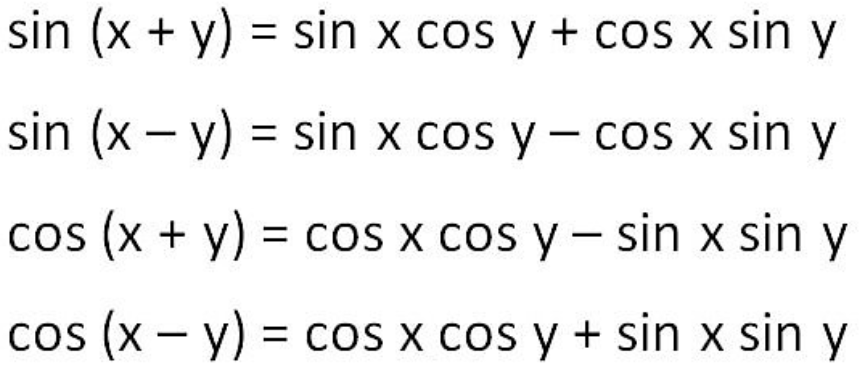

# Compensation Analysis

Assume $R_y(-\beta)$*$R_y(-\theta)$


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\cos \left(\beta +\theta \right)\,\ddot{x} -\frac{1}{l_n }\sin \left(\beta +\theta \right)\,\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


Expanding $\sin(\beta - \theta)$ and $\cos(\beta - \theta)$


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\left(c_{\beta } c_{\theta } -s_{\beta } s_{\theta } \right)\,\ddot{x} -\frac{1}{l_n }\left(s_{\beta } c_{\theta } +c_{\beta } s_{\theta } \right)\;\left(\ddot{z} +g\right)+\frac{d}{l_n }s_{\theta } \,{\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\;c_{\theta } \right)}\,\ddot{\beta} \,$$


**Linearized**

For small variations of $\theta$:


$$\ddot{\theta} =-\frac{b}{m}\dot{\theta} -\frac{1}{l_n }\left(-\theta \;s_{\beta \;} +c_{\beta } \right)\ddot{x} -\frac{1}{l_n }\left(s_{\beta } +\theta \;c_{\beta \;} \right)\left(\ddot{z} +g\right)+\frac{d}{l_n }\theta {\dot{\beta} }^2 -\frac{1}{l_n }{\left(l_n -d\right)}\,\ddot{\beta} \,$$


To eliminate centrifugal contributions of $\beta$ choose $d = l$:


$$\ddot{\theta} =-\frac{c}{m}\dot{\theta} -\frac{1}{l_n }\left(-\theta \;s_{\beta \;} +c_{\beta } \right)\,\ddot{x} -\frac{1}{l_n }\left(s_{\beta } +\theta \;c_{\beta \;} \right)\;\left(\ddot{z} +g\right)+\;\theta {\dot{\beta} }^2$$
 

**Compensation**

I we assume to have $\beta =-\tan^{-1} \left(\frac{\ddot{x} }{g+\ddot{z} }\right)=-\frac{c_u }{s_u }$


$$\ddot{\theta} =-\frac{c}{m}\dot{\theta} -\frac{1}{l_n }\left(-\theta \;\sin \left(\frac{c_u }{s_u }\right)+\cos \left(\frac{c_u }{s_u }\right)\right)\,\ddot{x} -\frac{1}{l_n }\left(-\sin \left(\frac{c_u }{s_u }\right)-\theta \;\cos \left(\frac{c_u }{s_u }\right)\right)\;\left(\ddot{z} +g\right)+\;\theta {\dot{\beta} }^2$$
 

To eliminate contributions of the external accelerations:


$$\left(\theta \;s_{\beta \;} +c_{\beta } \right)\,\ddot{x} =-\left(\theta \;c_{\beta \;} +s_{\beta } \right)\;\left(\ddot{z} +g\right)$$



$$\frac{\left(\theta \;c_{\beta \;} +s_{\beta } \right)}{\left(\theta \;s_{\beta \;} +c_{\beta } \right)}=-\frac{\ddot{x} }{\;\left(\ddot{z} +g\right)}$$


Impossible 